**Nonlinear Support Vector Machine. Kernel Gaussian. Dual Model**

Find the optimal separating surface for the data set given using a Gaussian kernel with parameters C = 1 and $\gamma$ = 1.

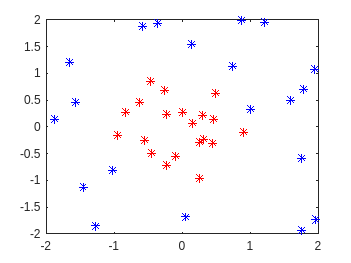

A = [0.0113    0.2713
    0.9018   -0.1121
    0.2624   -0.2899
    0.3049    0.2100
   -0.2255   -0.7156
   -0.9497   -0.1578
   -0.6318    0.4516
   -0.2593    0.6831
    0.4685    0.1421
   -0.4694    0.8492
   -0.5525   -0.2529
   -0.8250    0.2802
    0.4463   -0.3051
    0.3212   -0.2323
    0.2547   -0.9567
    0.4917    0.6262
   -0.2334    0.2346
    0.1510    0.0601
   -0.4499   -0.5027
   -0.0967   -0.5446];

B = [1.2178    1.9444
  -1.8800    0.1427
  -1.6517    1.2084
   1.9566   -1.7322
   1.7576   -1.9273
   0.7354    1.1349
   0.1366    1.5414
   1.5960    0.5038
  -1.4485   -1.1288
  -1.2714   -1.8327
  -1.5722    0.4658
   1.7586   -0.5822
  -0.3575    1.9374
   1.7823    0.7066
   1.9532    1.0673
  -1.0233   -0.8180
   1.0021    0.3341
   0.0473   -1.6696
   0.8783    1.9846
  -0.5819    1.8850];

% Plot the Dataset
plot(A(:,1), A(:,2), 'r*', B(:,1), B(:,2), 'b*');

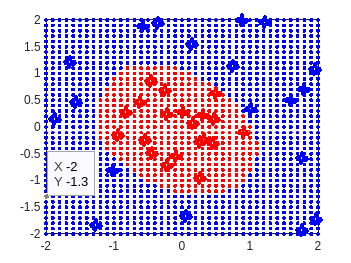

% Set environment variables
gamma = 1;
C = 1;
nA = size(A,1);
nB = size(B,1);

% Training Set 
T = [A;B];

y = [ones(nA,1); -ones(nB,1)];
l = length(y);

% Quadratic variables
f = -ones(l,1);
lb = zeros(l,1);
ub = C*ones(l,1);

K = zeros(l,l);
for i = 1:l
    for j = 1:l
        K(i,j) = exp(-gamma*norm(T(i,:)-T(j,:))^2);
    end
end

% Compute Q
Q = zeros(l,l);
for i = 1:l
    for j = 1:l
        Q(i,j) = y(i)*y(j)*K(i,j);
    end 
end

% Set the Problem
options = optimset('Largescale', 'off', 'Display', 'off');
[lambda, value] = quadprog(Q,f,[],[],y',0,lb,ub,[],options);

% Get b
indicator = find((lambda > 1e-3) & (lambda < C-1e-3));
i = indicator(1);
b = 1/y(i);
for j = 1:l
    b = b - lambda(j)*y(j)*K(i,j);
end

% Get general points 
AA = [];
BB = [];

for xx = -2:0.1:2
    for yy = -2:0.1:2
        s = 0;
        for i = 1:l 
            s = s + lambda(i)*y(i)*exp(-gamma*norm(T(i,:) - [xx yy])^2);
        end
        s = s + b;
        if s > 0 
            AA = [AA; xx yy];
        else 
            BB = [BB; xx yy];
        end
    end
end

% Plot the Nonlinear Support Vector Machine Dual Model Graph
plot(A(:,1), A(:,2), 'ro', B(:,1), B(:,2), 'bo', 'LineWidth',5);
hold on
plot(AA(:,1), AA(:,2), 'r.', BB(:,1), BB(:,2), 'b.');
hold off